# Convert Lookup to Speed Output

Our simulation study found the stopping height required for systems operating at different speeds and loads. However, we want a table that will take position and load and provide a maximum speed at the given conditions

## Visualize Range of Operation Results

Since the output of the simulation sweep is single-valued (for each unique load/speed combination, there is one stopping height), we can invert the table. Values outside of acceptable operational range will have a zero speed limit.

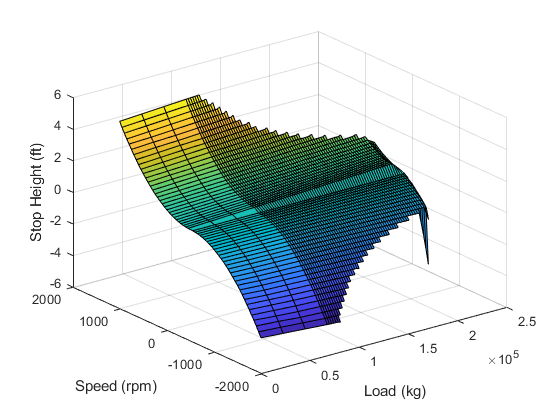

load DrawworksLimitData.mat;

surf(loadIn,spdLimitOut,distIn);
xlabel('Load (kg)');
ylabel('Speed (rpm)');
zlabel('Stop Height (ft)');

## Map Speed and Load to Distance

As the operation sweep has a range out output conditions (failed simulations output "inf" stopping distance, we need to pre-process the results. We will then use one-dimensional interpolation on the stopping distance.

#### Define Distance Vectors from Top and Bottom

distRaising = [0:0.1:5 6:1:48];
distLowering = [-48:1:-6 -5:0.1:0];
distSat = distIn;

#### Remove "Inf" Simulation Conditions

for j = 1:size(distSat,2)
    PosVal = 50;                        NegVal = -70;
    for i = 1:size(distSat,1)
        if distSat(i,j) == Inf
            distSat(i,j) = PosVal;      PosVal = PosVal + 1;
        elseif distSat(i,j) == -Inf
            distSat(i,j) = NegVal;      NegVal = NegVal + 1;
        end
    end
end

#### Interpolate using Defined Distance Vectors

for i = 1:numel(loadIn)
    stopDist = distSat(:,i);
    spdRaising(i,:) = interp1(stopDist,spdLimitOut,distRaising);
    spdLowering(i,:) = interp1(stopDist,spdLimitOut,distLowering);
end
spdRaising(isnan(spdRaising)) = 1500;   spdLowering(isnan(spdLowering)) = -1500;
spdRaising(spdRaising < 0) = 0;         spdLowering(spdLowering > 0) = 0;

## Visualize Speed-limit Lookup

The speed lookup table can be visualized on a surface plot. When operating, the speed command will be limited given the current distance from the top/bottom and the hook-load weight. To use this lookup in Simulink, the 2D lookup table blocks can be used. In the "drawWorks_withLookup" model, the lookup table approach is used in the Stateflow logic chart.

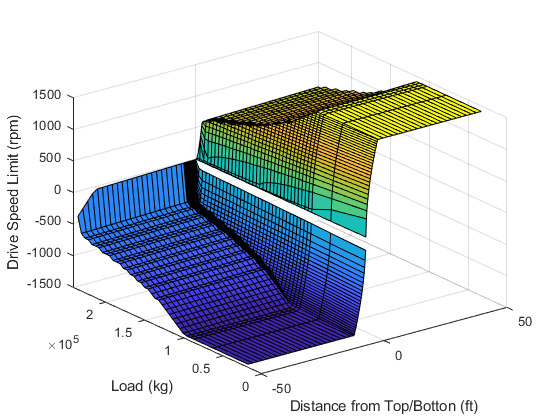

spcFact = 2;
figure();
surf(distLowering(1:spcFact:end),loadIn(1:spcFact:end),spdLowering(1:spcFact:end,1:spcFact:end)); hold on; 
surf(distRaising(1:spcFact:end),loadIn(1:spcFact:end),spdRaising(1:spcFact:end,1:spcFact:end));
xlabel('Distance from Top/Botton (ft)'); ylabel('Load (kg)'); zlabel('Drive Speed Limit (rpm)');